# Mobility framework

## Rigid Quadruped

We refer back to our previous work: [Geometric Mechanics of Nonslip Contact in a Planar Quadruped](https://arxiv.org/abs/2308.14357), where using a single level-set around the origin of the continuous shape subspace decoupled through shared stance, we tuned subgaits to achieve complicated average locomotion control and steering through a two-beat trot gait.

Here, using the mobility framework and discrete CCFs/stratified panels, we want to show that gait controllability is guaranteed.

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end

### Slip-nonslip coordinates

#### Generation

We package the tools from the previous discussion into a 'Path2_mobility' class.

Creating instances of 'Path2_mobility' to compute the slip and nonslip coordinates at two stance phase of a trot gait-cycle.

submanifoldIndex = 5; % we know that FR-HL stance phase is 5
integrationTime = 1.2*ones(1, 2); % set to paper 2 params for uniformity
refPtOrg = zeros(1, 2); % choose the reference point about which to compute
                        % the slip and nonslip directions
                        % ... we defaultly choose the orgin to first
                        % ... replicate our results from Paper 2.
FRHLstance = Path2_Mobility(submanifoldIndex, ...
                    kin, kinfunc, p_kin, p_info, ...
                    integrationTime, refPtOrg); % compute current stance

We identify the complementary submanifold using a static method in the "Path2_Mobility" class and then automatically construct and return that object.

FLHRstance = Path2_Mobility.constructComplementaryStance...
                    (FRHLstance, ...
                    kin, kinfunc, p_kin, p_info, ...
                    integrationTime, refPtOrg); % compute complementary stance

Save the stance phase data.

if exist(dataMobility, "file")
    save(dataMobility, "FRHLstance", "FLHRstance", "-append");
else
    save(dataMobility, "FRHLstance", "FLHRstance");
end

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the previous section.']);
end

#### Visualization

Let's plot this new coordinates for the two contact states in a trot gait.

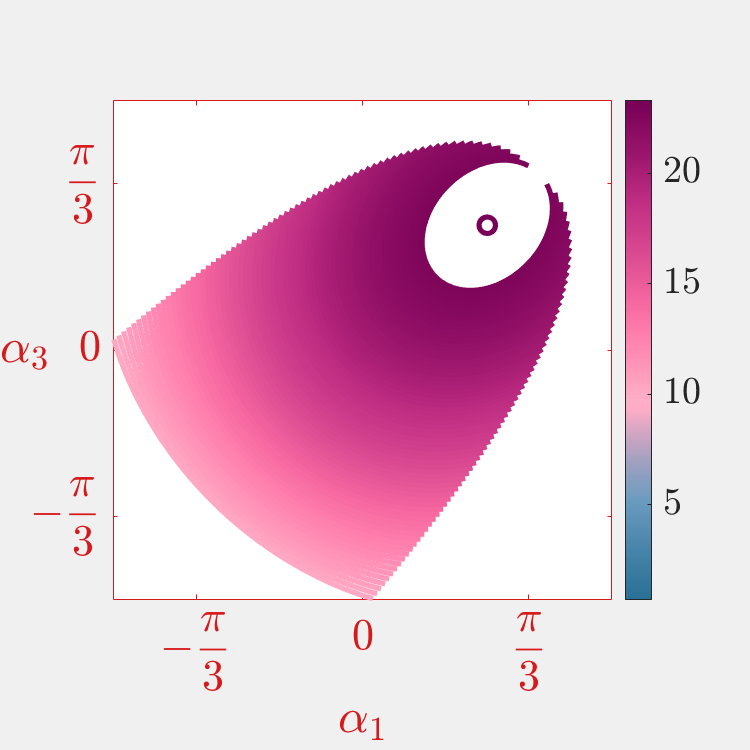

Path2_Mobility.visualizeNonslipLevelSets(FRHLstance)

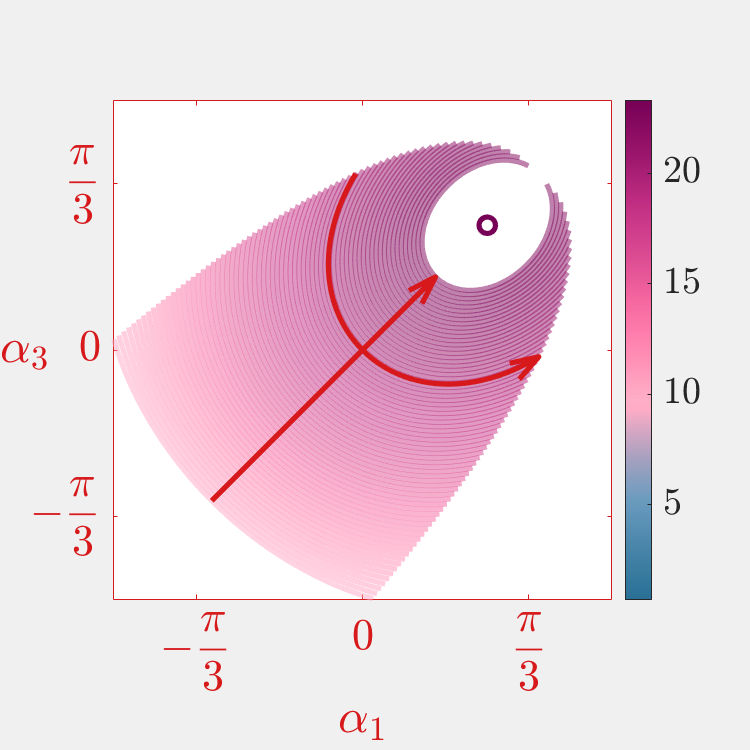

Path2_Mobility.visualizeSlipNonslipShapeCoordinates(FRHLstance)

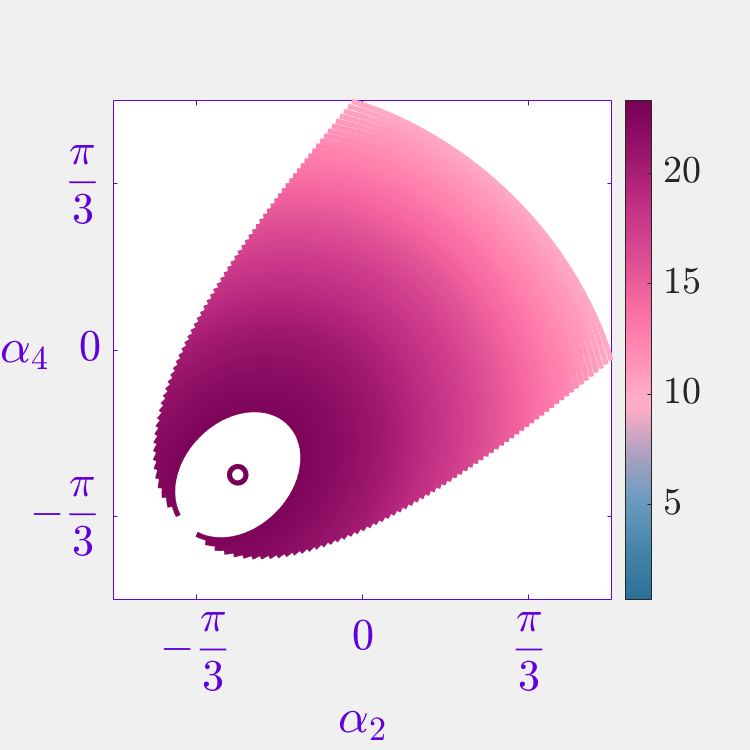

Path2_Mobility.visualizeNonslipLevelSets(FLHRstance)

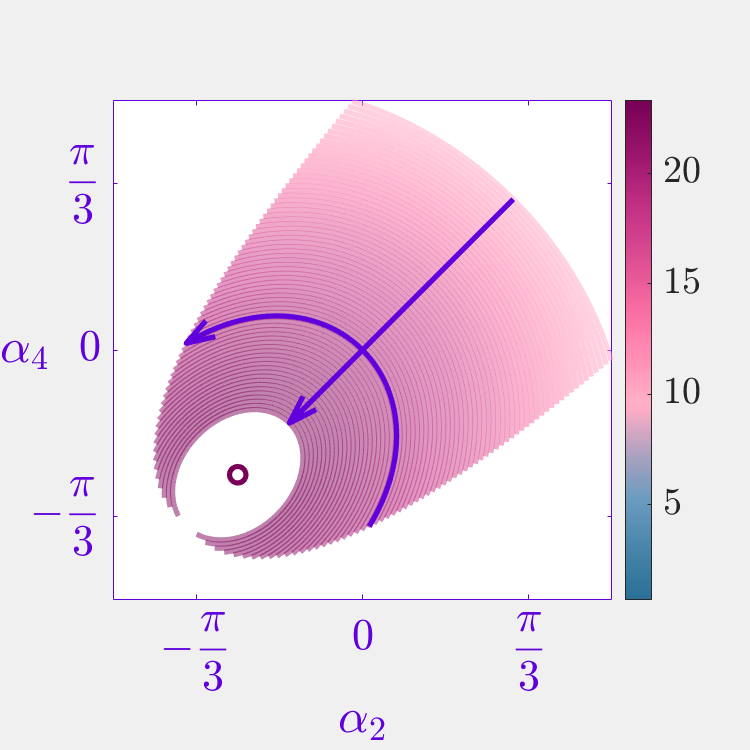

Path2_Mobility.visualizeSlipNonslipShapeCoordinates(FLHRstance)

Let's highlight the reference paths at $[0,0]$ where we shall carry out our mobility analysis.

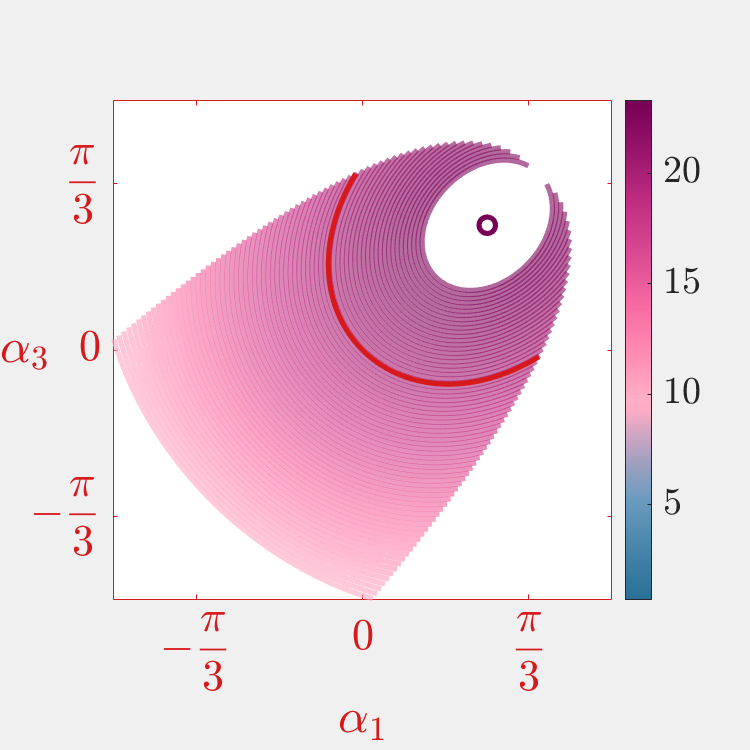

Path2_Mobility.highlightNonslipLevelSet(FRHLstance, zeros(1, 2))

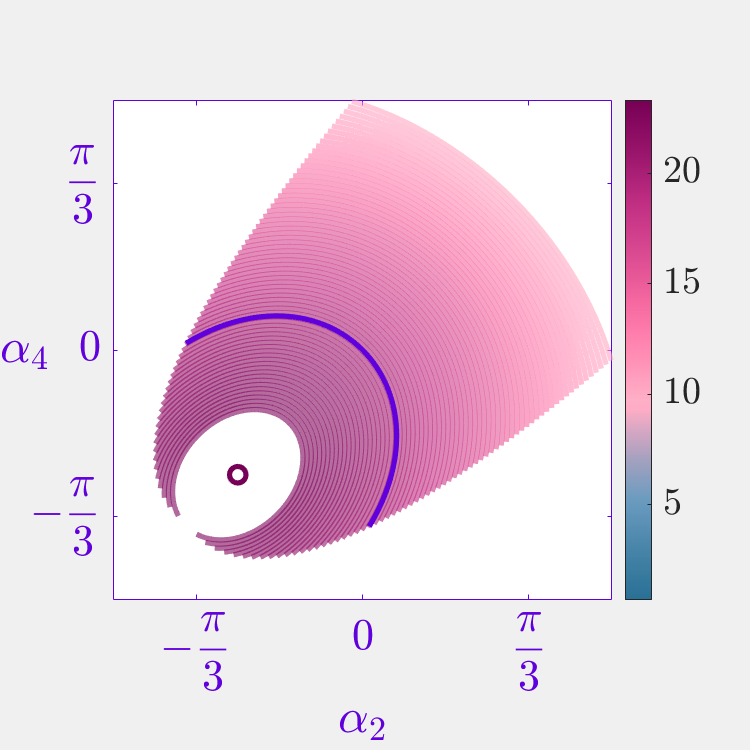

Path2_Mobility.highlightNonslipLevelSet(FLHRstance, zeros(1, 2))

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

### Noncommutative approximation of net-displacement

The goal is to not completely simulate the system for every combination of scaling and sliding inputs (for inputs, references, and parameters displayed in ["Geometrically Modulable Gait Design for Quadrupeds"](https://doi.org/10.1109/LRA.2024.3418311)) at different level-sets, and as the body parameter changes because it computationally expensive and doesn't allow us to quickly iterate over designs and gait-schedules.

In this section, we explore the requirements for approximating the net displacement obtained sequential stance paths arising from two-beat gaits. This would require combining the flows along the lie-algebra elements into one flow-- thus we use the BCH series to approximate the noncommutativity arising from such a choice. We first construct an trotting instance of the alternating quadrupedal gait class, "altQuadGait", using the "Path2_Mobility" class instances we generated earlier for pairs of diagonal legs that stance together.

% valid leaf mode arguments: "origin-only"
% valid input mode arguments: {"std", "path_limit_compliant"}
% ... if the input mode is "path_limit_compliant", we need integration
% ... limits; an example is commented at the end of the line below
rigidTrot = altQuadGait(FRHLstance, FLHRstance, "origin-only", "std") % , [-2, 2]

rigidTrot =   altQuadGait with properties:

              ithStance: [1×1 Path2_Mobility]
              jthStance: [1×1 Path2_Mobility]
    leafExplorationMode: "origin-only"
              inputMode: 'std'
      integrationLimits: [-Inf Inf]
            stanceSpace: [1×1 struct]
             inputSpace: []


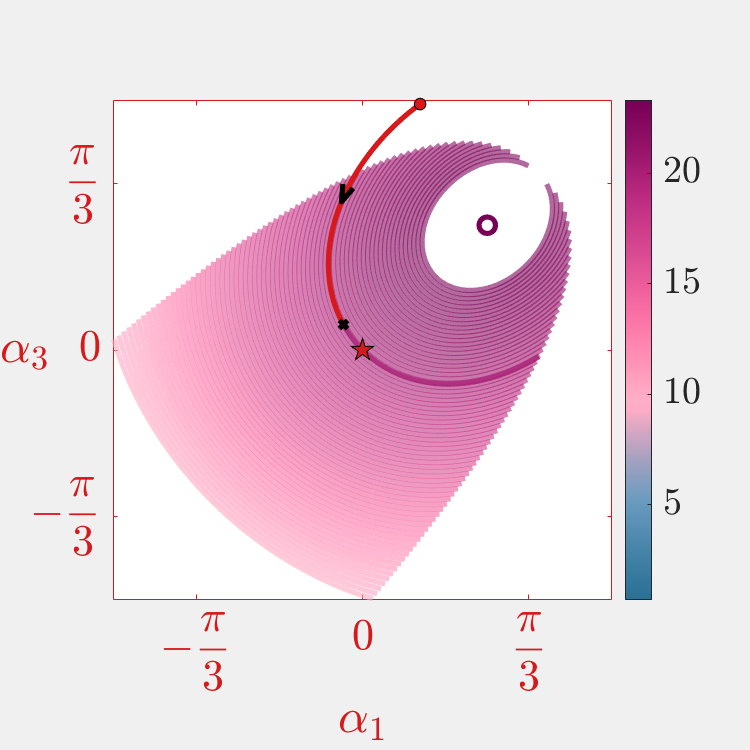

% ... switch input modes using this method:
% thisAltGait = alternatingQuadrupedalGait.switchInputMode(thisAltGait, "path_limit_compliant", [-2, 2]);
ref = []; 
ref.P = zeros(1, 2); ref.T = -0.8*ones(1, 2); % reference point and integration times to generate stance paths
% ... ... select trajectories from paper 2
% inputs = [+1.0, +0.0, +1.0, +0.0]; % traj 4, 9
% inputs = [+1.0, +0.5, +1.0, -0.5]; % traj 7
% inputs = [-1.0, +0.0, +1.0, +0.0]; % traj 10, 15
inputs = [-1.0, -1.0, +1.0, +1.0]; % traj 12
% ... ... 
ref13 = ref; ref24 = ref;
[ref13.tOff, ref13.tMax, FRHLstance] = Path2_Mobility.computeToffFromPerpCoord(ref.P, FRHLstance);
[ref24.tOff, ref24.tMax, FLHRstance] = Path2_Mobility.computeToffFromPerpCoord(ref.P, FLHRstance);
[tIC, tFC] = altQuadGait.computeGaitIntegrationTimes(    rigidTrot, ... % gait instance
                                                         inputs, ... % scaling and sliding inputs concatenated
                                                         [ref13.T,    ref24.T], ... % integration times
                                                         [ref13.tOff, ref24.tOff], ... % offset times
                                                         [ref13.tMax, ref24.tMax]   ); % max integration times
% ... final flag plots subgaits in shape subspace
configTraj13 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref13, ...
                                                     [tIC(1), tFC(1)], ...
                                                     FRHLstance, true);

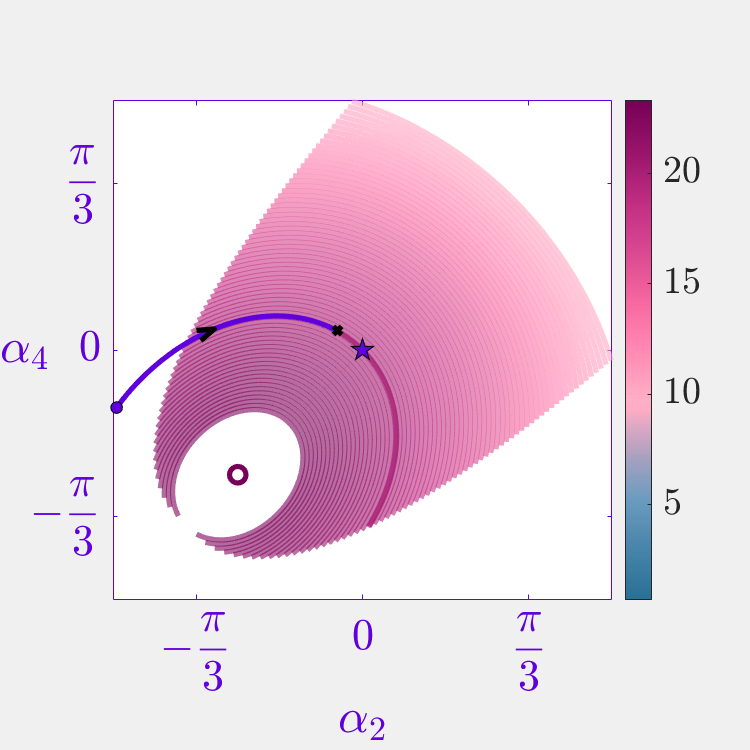

configTraj24 = Path2_Mobility.simulateConfigurationTrajectory...
                                                    (ref24, ...
                                                     [tIC(2), tFC(2)], ...
                                                     FLHRstance, true);

We need several different levels of body trajectory, more essentially **the net displacement approximation** from the individual stance trajectories we computed earlier. More details on these approximations are listed below in the order of compute:

- First, we use the exponentiated individual stance trajectories obtained using the local commutativity assumption and stitch them from front to back making it a **piecewise commutative approximation**.

- From this case, we assume the flows are happening simultaneously along the two lie-algebra elements from each stance phase. This will be a **joint, commutative approximation**.

- We add the second order term from the BCH expansion and make our first **joint, noncommutative approximation**.

- 3rd order added

- 4th order added

We are computing both the "complete" and "discretized" cases because for smaller scaling inputs, we believe the "discretized" case would provide coarser approximations under quicker compute times.

Let's visualize the body trajectory with the different levels of the lie-bracket estimates to analyze convergence and pickout the best and lowest order estimate. First we make a normal plot, then in the second one we zoom in and pick out the true differences in the net displacements.

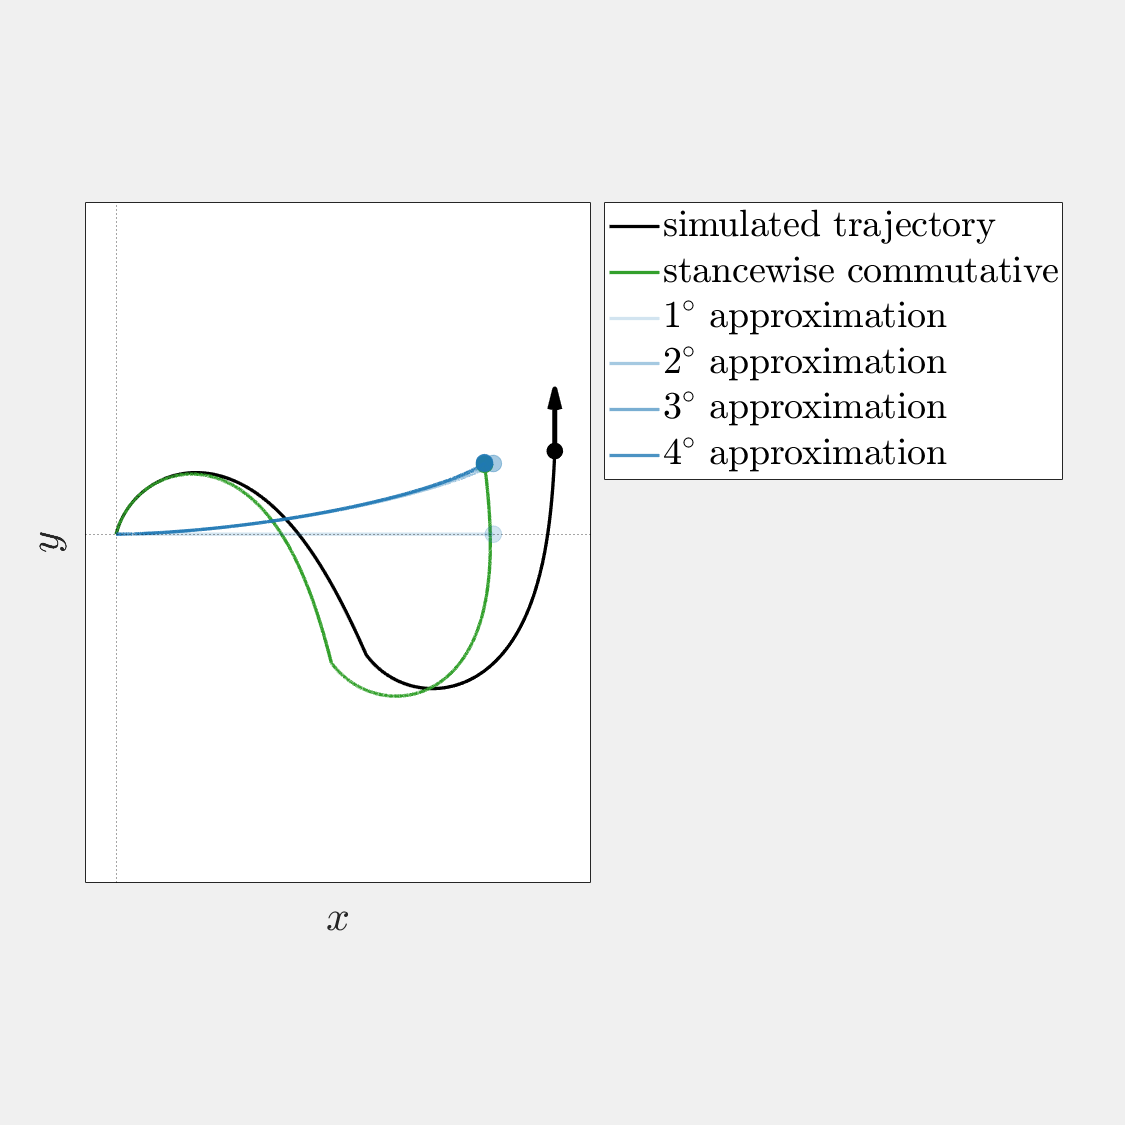

% obtain the complete configuration trajectory
% ... the second last argument is the maximum BCH expansion order needed to
% ... approximate the body trajectory; current it only supports order 4.
% ... --if it is zero, then only the simulated trajectory and stanceiwse
% ... commutative plots are presented
% ... --if the approximation order is left empty, then just the simulated
% ... trajectory is plotted
% ...
% ... the last binary arguments presence plots the body trajectory and its
% ... approximations and if true, repeats the plot without text so that we
% ... can zoom in obtain the differences between the estimates
jointStancePath = altQuadGait.fullCycleConfigTrajectory(rigidTrot, configTraj13, configTraj24, 4, false);

Also, plot the simulated trajectory as a timeseries.

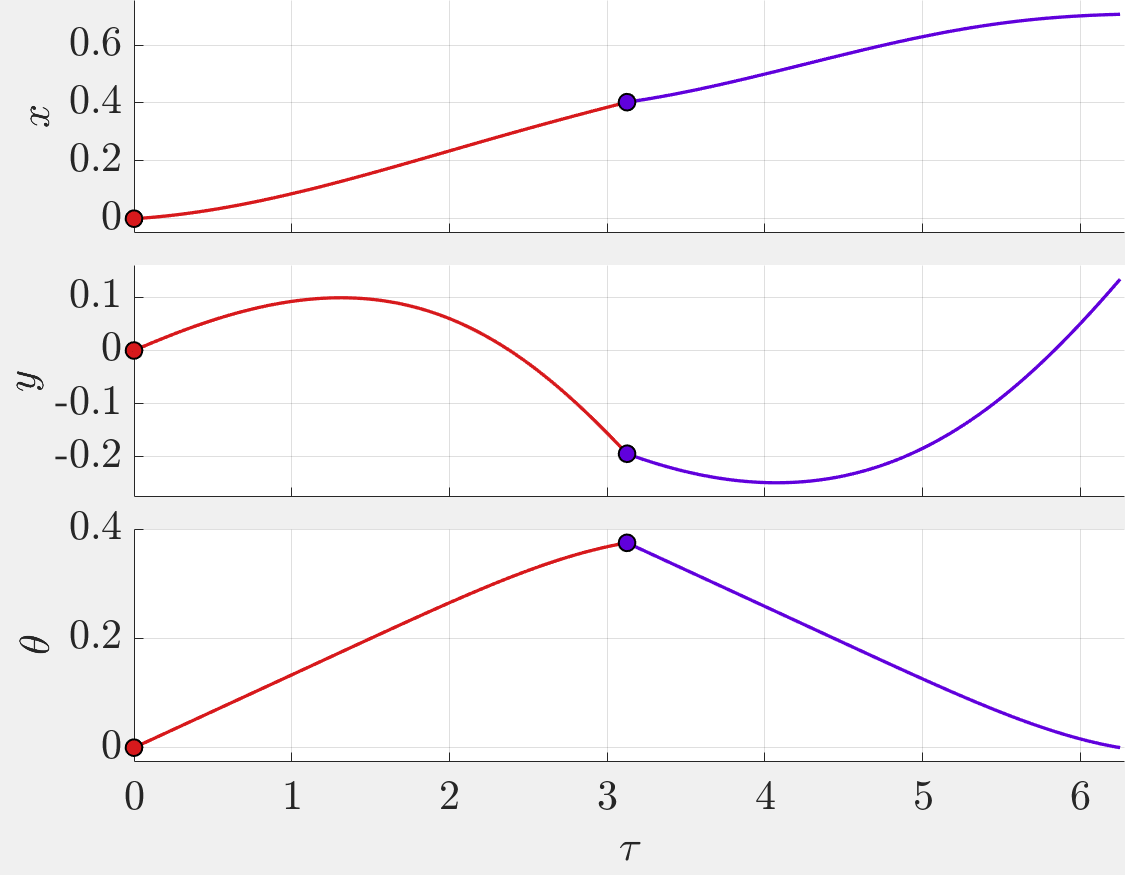

pltMode = 'stance_colored'; % options: 'stance_colored', 'k'
scatterFlag = true; % scatter dots at the beginning of each stance phase change % has use only during the 'stance_colored'
altQuadGait.plotBodyTimeseries(rigidTrot, configTraj13, configTraj24, pltMode, scatterFlag);

Save the results before plotting the trajectories.

if exist(dataMobility, "file")
    save(...
        dataMobility, ...
    "ref13", "ref24", "inputs", ...
    "FRHLstance", "FLHRstance", ...
    "configTraj13", "configTraj24", ...
    "rigidTrot", "jointStancePath", ...
    "-append"...
        );
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

While we use the complete trajectory information and discretized trajectory information in this example case, moving forward, we shall use lookup tables to obtain a much better estimate on how many time steps to have based on the path length. This lookup table is computed and stored as a property in the constructor. And, for exploring more global properties like the gait reachable set (of robot positions), we shall only need displacement point-clouds.

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

### Obtaining gait-plans

Next, we intend the visualize the subgait trajectories as a function of time. For this, we explicity compute them during stance phase, reverse the obtained trajectory (and condition the discretization) for the swing phase. The setup is very similar to the last section. More specifically, the 'Path2_Mobility' class method 'computeSubgaitInCoordinates' is very similar to the 'simulateConfigurationTrajectory' method. All of this is packaged into the method, "obtainGaitFSapproximation", in the new alternating quadrupedal gait class, "altQuadGait".

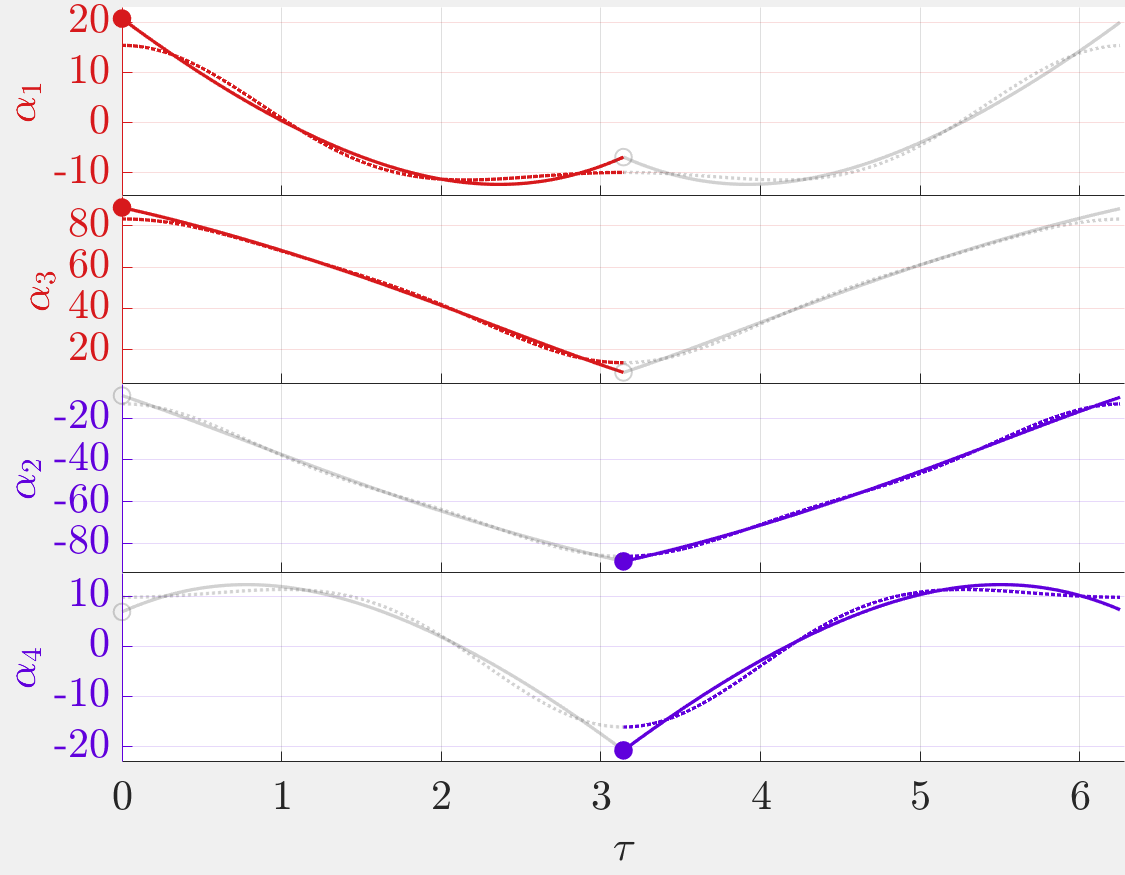

% definition of the references
% ... this can be changed by following the properties defined in the
% ... "Path2_Mobility" class for the instances 'FRHLstance' and
% ... 'FLHRstance' which correspond to limbs 13 and 24 respectively
ref = []; 
ref.P = zeros(1, 2); ref.T = -0.8*ones(1, 2);
% ... ... select trajectories from paper 2
% inputs = [+1.0, +0.0, +1.0, +0.0]; % traj 4, 9
% inputs = [+1.0, +0.5, +1.0, -0.5]; % traj 7
% inputs = [-1.0, +0.0, +1.0, +0.0]; % traj 10, 15
inputs = [-1.0, -1.0, +1.0, +1.0]; % traj 12
% set the each reference
ref13 = ref; ref24 = ref;
% obtain the fourier series approximation for the current reference and
% inputs
% ... the approximation order is 3 because currently that's the upper-limit
% ... of our embedded firmware-hardware capabilities
% ... keeping the plot structure (second last input) to 
% ... flag:'true' and mode:'stance_colored'
% ... keeping the .csv exporter of the FS coefficients flag to 'false'
pltStruct = []; 
    pltStruct.flag = true; 
        pltStruct.mode = 'stance_colored'; % options: 'stance_colored', 'k'
genCSVflag = false;
[pFS, subGT, subGTFS] = ...
                    altQuadGait.obtainGaitFSapproximation...
                        (rigidTrot, ref13, ref24, inputs, ...
                                3, pltStruct, genCSVflag);

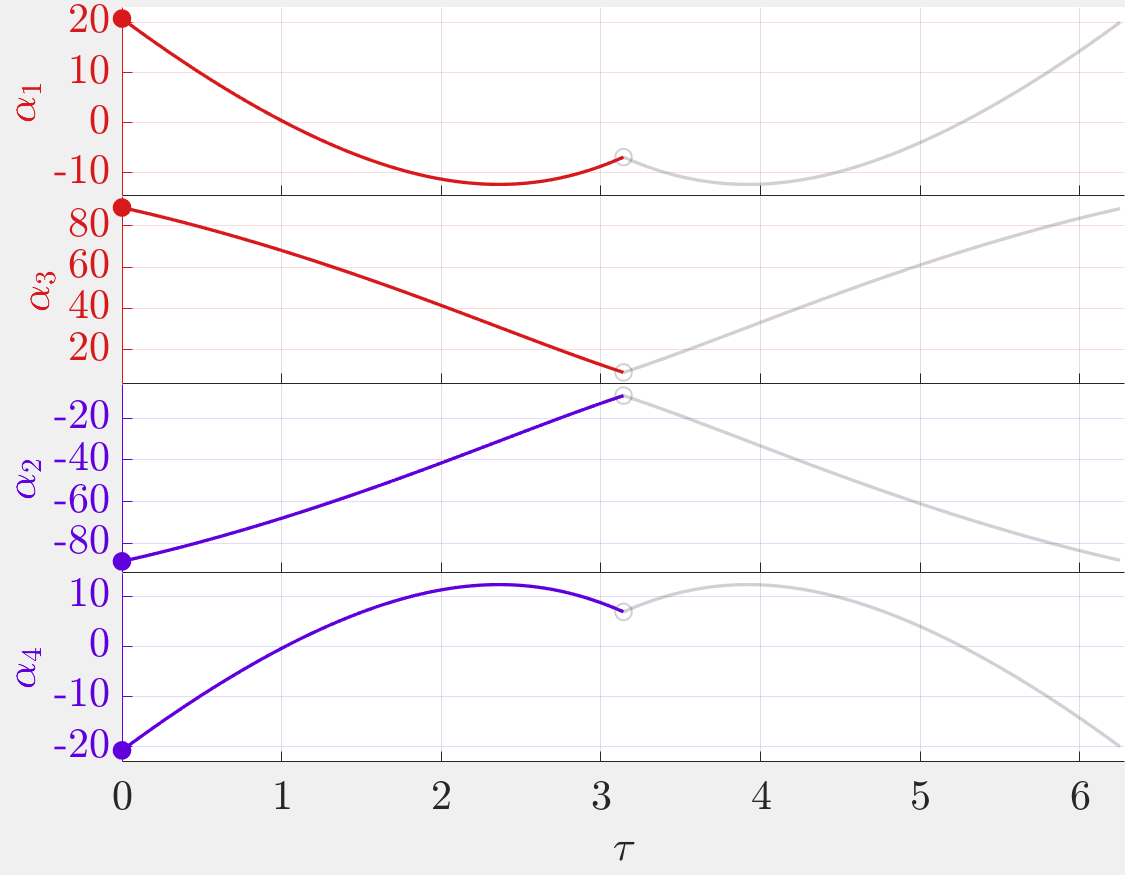

altQuadGait.plotShapeTimeseries(rigidTrot, ref13, ref24, inputs, pltStruct);

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

### Local connection and curvature in the stance space

The two leafs of the foliation in the shape subspaces induced by the squared-inter leg distance, $F$, form their own subspace over which paths along $x$ indicate stance phase paths during the first subgait and similarly, paths along $y$ indicate stance paths during the second subgait. Because the stratified panels, $dz$, or the connection vector fields in the stance space, $\mathbf{A}_{i} \text{ or } \mathbf{A}_{j}$, are conservative (nonslip constraint is holonomic and the current $F$ value is conserved), these individual paths in each direction can be combined in a path independent way from the initial point in each stance phase to the final point at the end of each stance phase.

Here, we obtain a description of the local connection in the stance space, its lie-bracket (local curvature form because the vector fields are conservative), and the dot product between the two vector field directions to discuss their span for gait controllability arguments.

The connection or stratified panels:

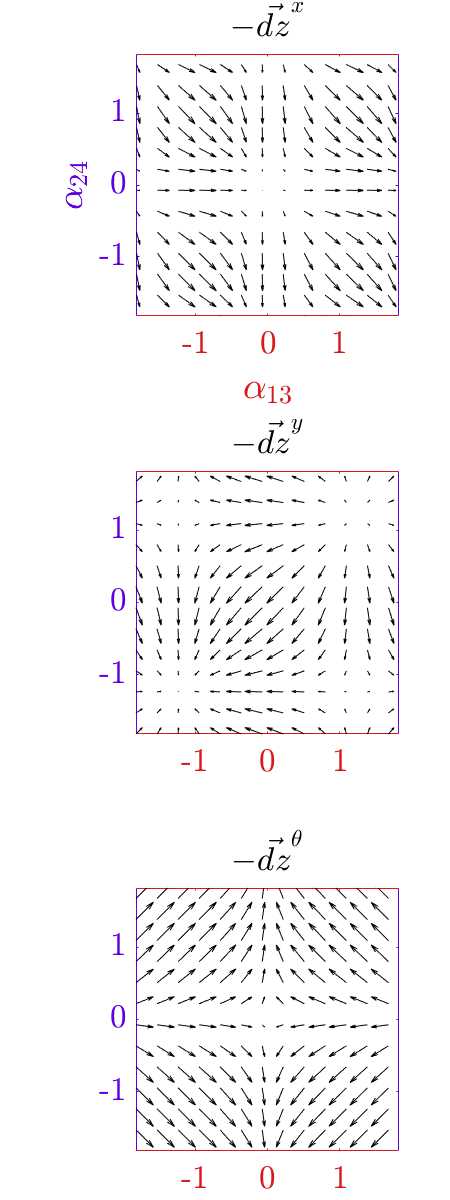

altQuadGait.plotStanceSpacePanels( rigidTrot );

The lie-bracket or the local curvature form ($\theta$-direction is ignored as it is uniformly zero):

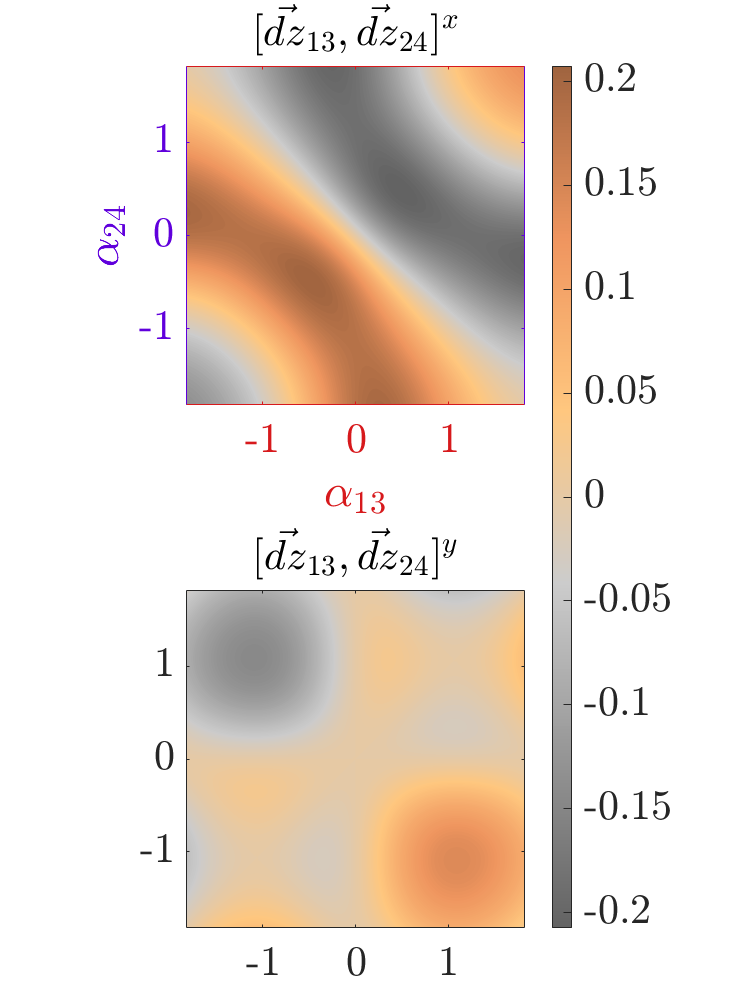

altQuadGait.plotStanceSpaceCurvature( rigidTrot );

The normalized dot product (span drops when the contours are either 1 or -1 when $dz_i$ or $dz_j$ are aligned):

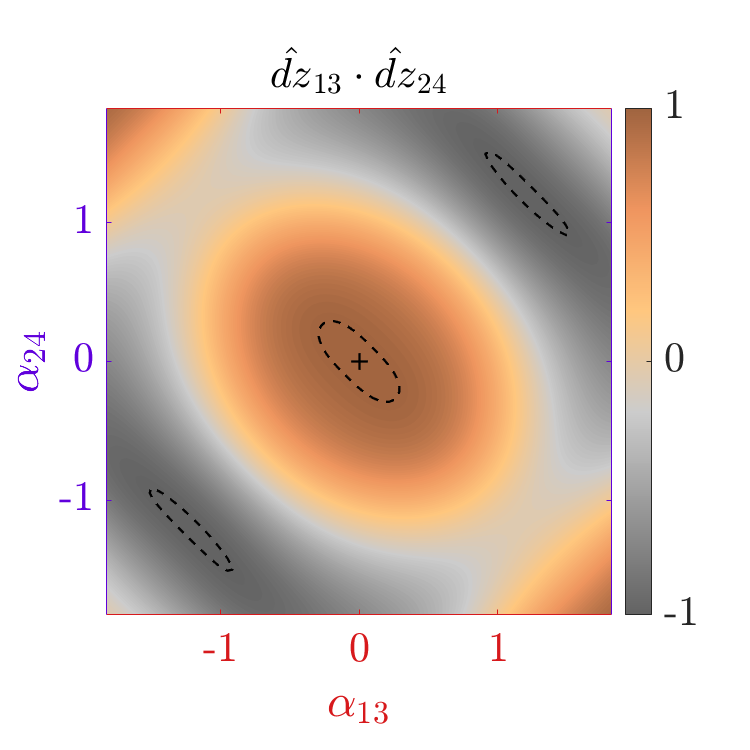

altQuadGait.plotStanceSpaceInterpanelDotProduct( rigidTrot );

We notice that the span of the panels in the stance space drops down to $1$ or $-1$ at exactly three points (mountains and valleys) circled in the above contour. So, for a path with any nonzero length, we will only spend an instant at one of these points-- and thus preserved our span for the most part. Also, note that the zero-contours of the panels coincide at the origin where the span becomes a 1D set.

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

### Input space and mobility

#### Computing the set of gait-driven body displacements

In this section we shall analyze the rigid quadruped's reachable set while trotting in two ways-- one in terms of the net displacement and the other in terms of the groupwise velocity that generates that displacement. Then, we shall scale the displacement with the cost to execute a gait cycle to obtain an efficiency formulation akin to the work in the paper: [Geometric Mechanics of Contact-Switching Systems](https://ieeexplore.ieee.org/abstract/document/10297561).

For this, we still divide the input space in two, two-dimensional arrays meshgrid arrays as the alternating gaits are in decoupled spaces. For the ground-truth reachable set and a constant input  discretization, $`n'$, the simulation takes place in the decoupled spaces ($2 n^2$ simulations) and we exponentiate the two displacements to obtain the overall displacement ($n^4$ exponentiations). Although not verified, this is provably much cheaper than directly simulating the whole space ($n^4$ simulations). 

We follow the same appraoch for the estimation part where we first obtain a path length (euclidean length driven discretization lookup table), the inital and final times for the estimation procedure, the panels, and the first-order Lie-bracket of the panels as function of the previously considered decoupled input subspaces. We do not perform approximations past the 2nd order of the BCH expansion (only the first order lie-bracket is involved) as our previous explorations of noncommutativity in stance space paths didn't require such high orders to approximate the piecewise noncommutative estimate. Once we have the sweeps in the decoupled input spaces, we obtain the displacement through the full simulation, piecewise commutative approximation, and  the first and second order reachable set estimates.

% Path length
% ... we setup the integration times for unit path-length as in paper 2
T = repmat({-0.8*ones(1, 2)}, 1, 2);

% Input discretization
% ... discretizing each input dimension into a certain number of points
% ... keep this odd (>= 3) so that we always get the origin
dNumU = 21; % 3, 5, 7, 9, 11 % add more after testing
% SIMULATES {11pts: 300ms, 21pts: ~30s}

% Generate the Input Space
% ... we generate the input space with input sweeps and other integration
% ... related parameters to simulate and estimate the system's response
rigidTrot = altQuadGait.generateInputSpace( rigidTrot, dNumU, T );

% Simulate the Input Space
% ... here, we first simulate the input subspaces
% ... then in nested FOR (~4) loops, we compute the displacement as a
% ... function of the entire input space
tic; rigidTrot = altQuadGait.simulateInputSpace( rigidTrot ); toc;

Elapsed time is 28.696291 seconds.


% Save the instance once more
inputSpace = rigidTrot.inputSpace;
if exist(dataMobility, 'file')
    save(dataMobility, "rigidTrot", "-append");
else
    save(dataMobility, "rigidTrot");
end

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist(dataName, "file")
    load(dataName);
else
    error(['ERROR! The base kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx".']);
end
if exist(dataMotPlanName, "file")
    load(dataMotPlanName);
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end
if exist(dataMobility, "file")
    load(dataMobility);
else
    error(['ERROR! The mobility kinematics data file is needed. ' ...
        'Create one in the first section of this livescript.']);
end

#### Visualizing the gait-driven body reachable sets

Here, we shall evaluate the gait-driven reachble set in the displacement space along the $\mathit{SE}(2)$ directions. Note that for this set, we used the standard input formulation from ["Geometrically Modulable Gait Design for Quadrupeds"](https://doi.org/10.1109/LRA.2024.3418311).

% unpack the reachable set
z = rigidTrot.inputSpace.sim.z;
zX = z{1}(:); zY = z{2}(:); zYaw = z{3}(:);
% assign boundaries
% ... first to the 3D set
% ... next to the 2D projections
% ... these things make the set easier to visualize
fullyShrunkBoundary3D = boundary(zX, zY, zYaw, 1);
fullyShrunkBoundary2D = cell(1, 3); idxCyclic = 1:3;
for i = 1:3
    fullyShrunkBoundary2D{i} = boundary(z{idxCyclic(1)}(:), z{idxCyclic(2)}(:), 1);
    idxCyclic = circshift(idxCyclic, -1);
end
idxCyclic = circshift(idxCyclic, -1); % back to original ordering
% define some strings for plotting
dirnLabelTxt = {'Lateral (x)', 'Longitudinal (y)', 'Rotational ($\theta$)'};

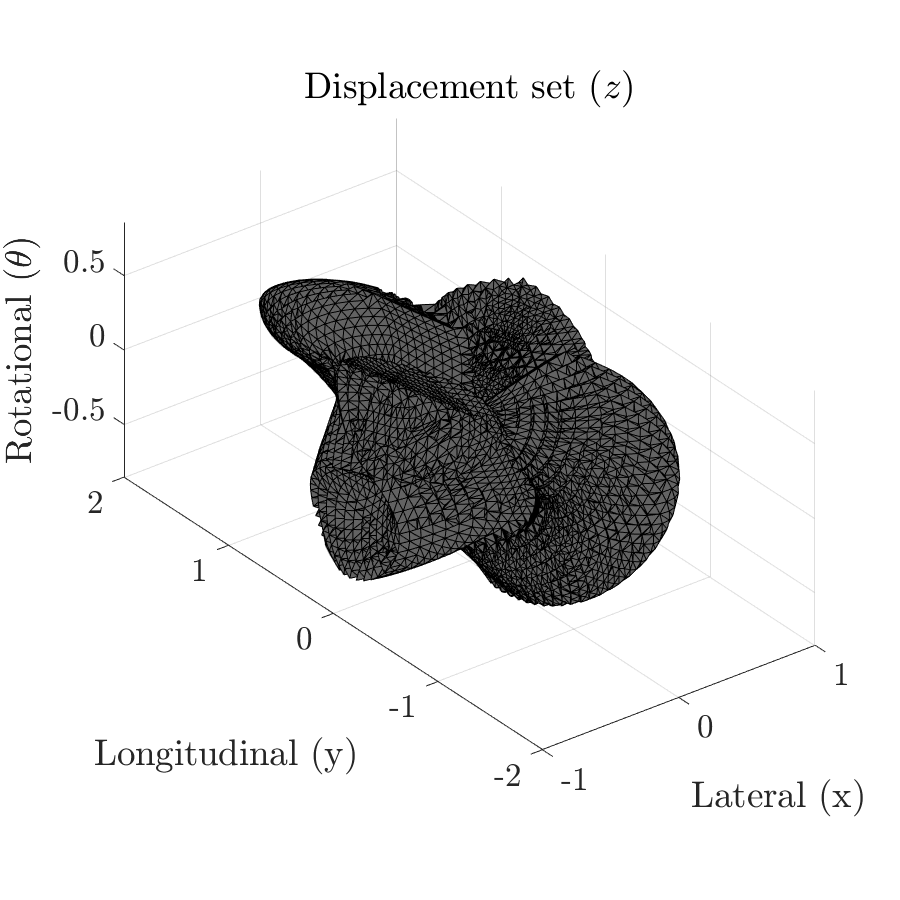

fS = 25; panelFaceColor = 99/255*ones(1, 3);
figure('units', 'pixels', 'position', [0 0 900 900], ...
                'Color','w','Visible','on'); ax = gca;
trisurf(fullyShrunkBoundary, zX, zY, zYaw, ...
    'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelFaceColor);
axis(ax, "equal", "padded"); ax.FontSize = fS; title(ax, 'Displacement set ($z$)');
xlabel(ax, 'Lateral (x)'); 
ylabel(ax, 'Longitudinal (y)'); 
zlabel(ax, 'Rotational ($\theta$)');

Same figure in three different 2D projections.

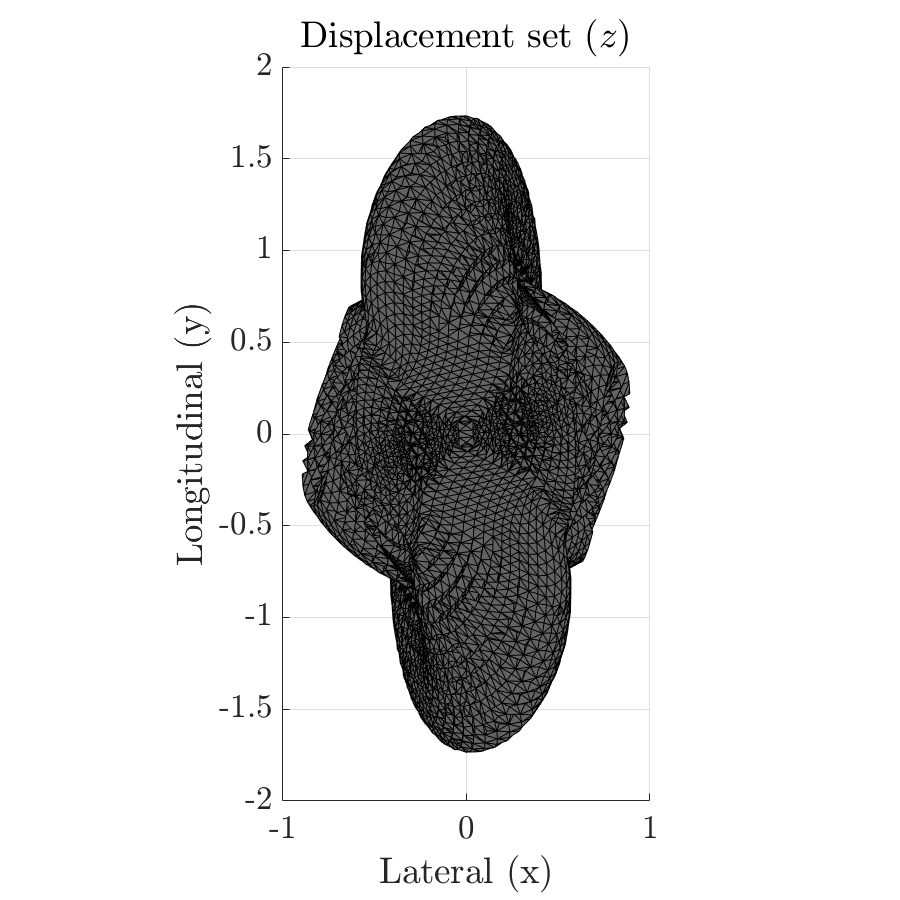

fS = 25;
figure('units', 'pixels', 'position', [0 0 900 900], ...
                'Color','w','Visible','on'); ax = gca;
trisurf(fullyShrunkBoundary, zX, zY, zYaw, ...
    'LineWidth', 0.1, 'LineStyle', '-', 'FaceColor', panelFaceColor);
axis(ax, "equal", "padded"); ax.FontSize = fS; title(ax, 'Displacement set ($z$)');
xlabel(ax, 'Lateral (x)'); view(0, 90);
ylabel(ax, 'Longitudinal (y)'); 
zlabel(ax, 'Rotational ($\theta$)');

Fully 2D plots in each of the planes with the boundary.

f = figure('units', 'pixels', 'position', [0 0 1200 1200], ...
                'Color','w','Visible','on');
tl = tiledlayout(f, 1, 3, "TileSpacing", "tight", "Padding", "tight");
for i = 1:3
    ax = nexttile(tl);
end